# **Implementação do teste Kolmogorov-Smirnov**

**    Alunos:**

- 1411 - Danilo Vidal Ribeiro

- 1354 - Luana Gribel Ito

## **Amostras para o exercício 7.32 - (sample75)**

samples75 = [16, 14, 12, 13, 10, 13, 17, 14, 11, 13, 17, 14, 16, 11, 15, 15, 13, 18, 12, 15, 15, 16, 12, 14, 14, 16, 15, 14, 13, 12]

samples75 =     16    14    12    13    10    13    17    14    11    13    17    14    16    11    15    15    13    18    12    15    15    16    12    14    14    16    15    14    13    12


## **Amostras para o exercício 7.33 - (sample76)**

samples76 = [18, 17, 17, 16, 16, 16, 18, 16, 14, 11, 16, 12, 17, 18, 17, 18, 18, 16, 18, 18, 11, 13, 17, 17, 17, 15, 16, 17, 15, 10]

samples76 =     18    17    17    16    16    16    18    16    14    11    16    12    17    18    17    18    18    16    18    18    11    13    17    17    17    15    16    17    15    10


### Selecione qual amostra deseja realizar o teste de normalidade e o nível de significância:

#### (sample75 ou sample 76)

samples = samples76

samples =     18    17    17    16    16    16    18    16    14    11    16    12    17    18    17    18    18    16    18    18    11    13    17    17    17    15    16    17    15    10


significancia = 0.150

significancia = 0.1500

m = mean(samples)

m = 15.8333

s = std(samples)

s = 2.2907

l = length(samples)

l = 30

x = (samples - m) / s

x =     0.9459    0.5093    0.5093    0.0728    0.0728    0.0728    0.9459    0.0728   -0.8004   -2.1100    0.0728   -1.6735    0.5093    0.9459    0.5093    0.9459    0.9459    0.0728    0.9459    0.9459   -2.1100   -1.2369    0.5093    0.5093    0.5093   -0.3638    0.0728    0.5093   -0.3638   -2.5466


[h,p,ksstat,cv] = kstest(x,"Alpha",significancia);
fprintf('-----------------------\n')

-----------------------


fprintf('Mean: %6.2f\n', m)

Mean:  15.83


fprintf('StDev: %6.3f\n', s)

StDev:  2.291


fprintf('N: %i\n', length(samples))

N: 30


fprintf('KS: %6.3f\n', ksstat)

KS:  0.262


if(p >= significancia)
    fprintf('P-Value: > %6.3f\n', significancia)
elseif (p < significancia)
    fprintf('P-Value: < %6.3f\n', significancia)
end

P-Value: <  0.150


fprintf('P-Value: %6.3f\n', p)

P-Value:  0.026


fprintf('-----------------------\n')

-----------------------


if(h == 0)
    fprintf('H%i: A amostra apresenta normalidade em suas distribuições\n', h)
elseif(h == 1)
    fprintf('H%i: A amostra NÃO apresenta normalidade em suas distribuições\n', h)
end

H1: A amostra NÃO apresenta normalidade em suas distribuições


fprintf('Nível de significância: %6.2f porcento%\n', significancia * 100)

Nível de significância:  15.00 porcento

fprintf('-----------------------\n')

-----------------------


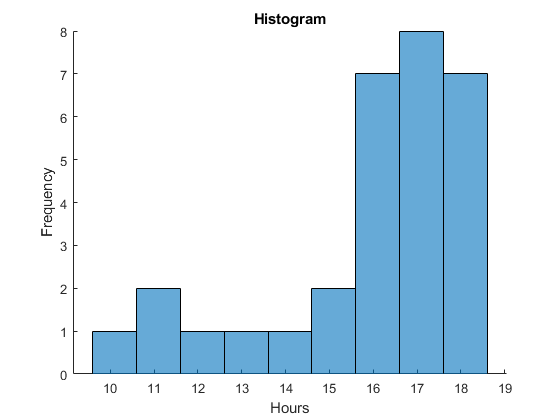

figure
hold on
histogram(samples,9)
title("Histogram")
xlabel("Hours")
ylabel("Frequency")

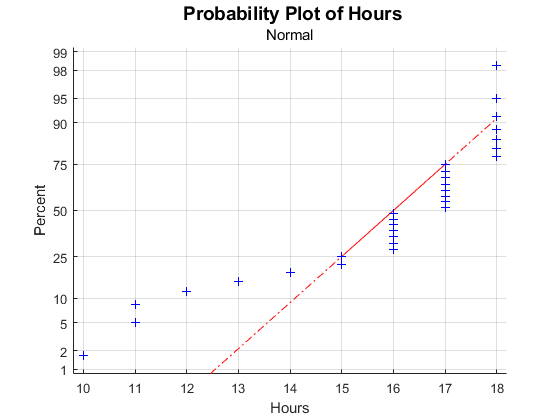

figure
hold on
normplot(samples)
title({'{\bf\fontsize{14} Probability Plot of Hours}'; 'Normal'},'FontWeight','Normal')
yticklabels(str2double(yticklabels()) * 100)
xlabel("Hours")
ylabel("Percent")